# Function Workspace

## Discretization methods

The discretization method for workspace determination is wide-spread and straightforward to apply on examples. Most authors used regular grids to approximate the workspace. For this method, one need to defines a range from minimal to maximal values. Then, the range will be tested with a given step size.  

The benefits of discretization methods are: 

- A straightforward and easy implementation 

- simple visualisation of the workspace

- no assumtions about the topological structure of the workspace are needed. (Parallel robot is more about its topology than its geometry)

- No assumptions need to be made for the geometric structure. 

- Volume calculation is straightforward, by using the number of samples that belongs to the workspace. 

The limitation of discretization methods are: 

- The determination of workspace boundary is not smooth and inaccurate. 

- The information about the empty space between the workspace volume. 

- Time consuming computation. Higher resolution, more time and computational power is needed.

In this function, the rotation angles in z-direction and also the rotation angles at 3D axis has been defined. So the main focus in this file is the iterative loop for the translation in z-axis. As the following figure shows, the same plot has been gnerated, but with the translation of z-axis. The step size can be viewed from the variable ***grid_n.*** 

## ewrewr

### fdsfs

#### dasd

fasda

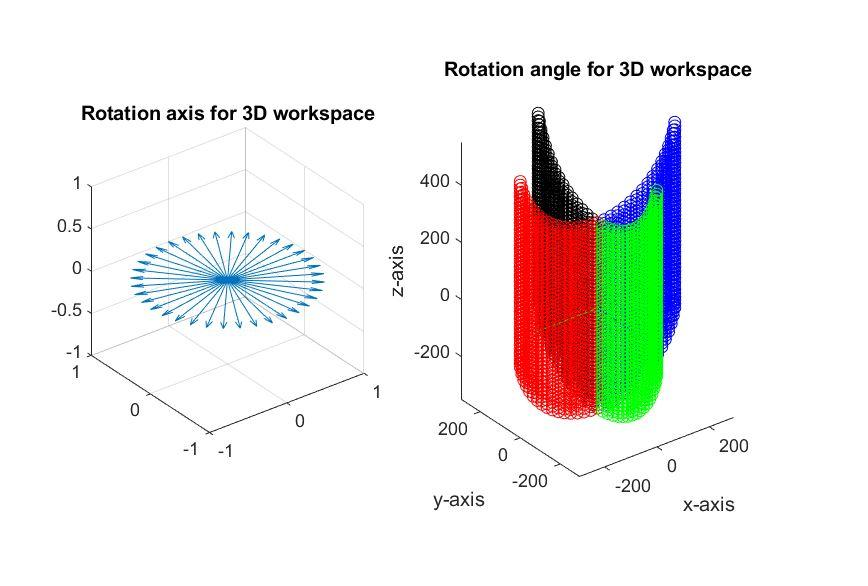

function [workspace_logical, cable_length_mat] = workspace_khaw_live(a, f_min, f_max,noC, b_rot_xy, w_p, w_p_t, workspace_logical, coordinate, limit, f_M, wrench_mat)

cable_length_cell = cell(1,length(coordinate.z)); %preallocating for speed

       %Go through all the coordinate of z-axis, and save them in variable workspace_position 
       for k = 1:length(coordinate.z)
           workspace_position = [coordinate.x coordinate.y coordinate.z(k)]'; %workspace_position in a column vector  

            if w_p == 0 && w_p_t == 0
                wrench = zeros(6,1);
                [stop] = berechnungSeilkraftverteilung_KHAW(workspace_position, a, f_min, f_max,noC,b_rot_xy, wrench, limit,f_M);
                workspace_logical(k) = ~stop; %write the logical for 1 if stop = 0 (no violation exist)
            else

                for index_wp = 1:size(wrench_mat,2)
                    wrench = wrench_mat(:,index_wp); 
                    [stop,cable_length] = berechnungSeilkraftverteilung_KHAW(workspace_position, a, f_min, f_max,noC, b_rot_xy, wrench, limit,f_M); 
                   if stop == 1
                       break
                   end

                end

                if stop == 0 
                   cable_length_cell{k} = cable_length;
                   workspace_logical(k) = true; %write the logical for 1 if stop = 0 (no violation exist)
                else
                    workspace_logical(k) = false; %write the logical for 0 if stop = 1 (violation exist)
                end

            end
       end

       cable_length_mat = cat(1,cable_length_cell{:});

end